# Gantt Chart SPK

clc;  
clear all; 
close all; 
% rng('default'); 
% T = [1 randi([10 20])
%      2 randi([10 20])
%      3 randi([10 20])
%      4 randi([10 20])
%      5 randi([10 20])]

% D = projectscheduling(T)
% %ganti D pake interval index awal sampe akhir?
% %ganti D pake 

% Positions=zeros(1,5); % vertical axis coordinates
% plotLengths = zeros(5,2);
% for i =1:5
%     Positions(1,i) = D(i,1);
%     plotLengths(i,1) = D(i,2);
%     plotLengths(i,2) = D(i,3)-D(i,2);
% end

% Positions=zeros(1,5); % vertical axis coordinates
% plotLengths = zeros(5,2);
% for i =1:5
%     Positions(1,i) = D(i,1);
%     plotLengths(i,1) = D(i,2);
%     plotLengths(i,2) = D(i,3)-D(i,2);
% end

% H = barh(Positions,plotLengths,'stacked');

% set(H(1),'Visible','off');
% 
% xlim([3.3 94.2])
% ylim([0.36 6.18])

% x = [1980 1990 2000 2010 2015]
% y = [8 15 25 26; 30 35 40 45; 50 55 62 70; 64 70 75 80; 76 79 85 92]
% % Stacked
% ax2 = nexttile;
% z = barh(ax2,x,y,'stacked')
% title('Stacked Style')

% abc = 2:length(x)-1

% for q = 2:length(x)-2
%     q
%     x = set(z(q),'Visible','off');
% end

%p = [8 8 2 2 9 9 7 7 4 4 10 10 5 5 3 3 6 6 1 1]
%p = [2 2 1 1 10 10 9 9 6 6 8 8 5 5 7 7 4 4 3 3]
p = [1 1 1 10 10 10 6 6 6 7 7 7 5 5 5 8 8 8 4 4 4 2 2 2 3 3 3 9 9 9]

p =      1     1     1    10    10    10     6     6     6     7     7     7     5     5     5     8     8     8     4     4     4     2     2     2     3     3     3     9     9     9


%p = [1 3 3 3 3 3 1 7 7 7 7 7 1 1 1 9 9 9 9 9 4 4 4 4 4 2 2 2 2 2 8 8 8 8 8 10 10 10 10 10 5 5 5 5 5 6 6 6 6 6]

[unique_value,first_jp_idx,~] = unique(p,'first','legacy')

unique_value =      1     2     3     4     5     6     7     8     9    10


first_jp_idx =      1    22    25    19    13     7    10    16    28     4


[~,second_jp_idx,jp] = unique(p,'last','legacy')

second_jp_idx =      3    24    27    21    15     9    12    18    30     6


jp =      1     1     1    10    10    10     6     6     6     7     7     7     5     5     5     8     8     8     4     4     4     2     2     2     3     3     3     9     9     9


n_release_col = 1:10

n_release_col =      1     2     3     4     5     6     7     8     9    10


release_column = [n_release_col' first_jp_idx' second_jp_idx']

release_column =      1     1     3
     2    22    24
     3    25    27
     4    19    21
     5    13    15
     6     7     9
     7    10    12
     8    16    18
     9    28    30
    10     4     6


graph_col = [first_jp_idx' second_jp_idx']% (second_jp_idx')-(first_jp_idx') , release_column(1:end,2:3)

graph_col =      1     3
    22    24
    25    27
    19    21
    13    15
     7     9
    10    12
    16    18
    28    30
     4     6


% ax2 = nexttile;
% z = barh(ax2,n_release_col,graph_col(1:end,2),'stacked')

%https://www.mathworks.com/matlabcentral/answers/1891675-how-do-i-plot-gantt-chart-for-scheduling
%https://www.mathworks.com/matlabcentral/answers/295207-add-y-grid-only-to-plot
%https://www.mathworks.com/matlabcentral/answers/16751-how-to-change-the-values-of-x-axis-and-y-axis
%https://www.mathworks.com/campaigns/offers/data-science-cheat-sheets.html?s_iid=mwa_ds_cht_shts
%https://www.mathworks.com/help/matlab/creating_plots/combine-multiple-plots.html

width = .75; % vertical width of horizontal bars
ypairs = release_column(:,1) + width./[-2,2];
y = repelem(ypairs,1,2)

y =     0.6250    0.6250    1.3750    1.3750
    1.6250    1.6250    2.3750    2.3750
    2.6250    2.6250    3.3750    3.3750
    3.6250    3.6250    4.3750    4.3750
    4.6250    4.6250    5.3750    5.3750
    5.6250    5.6250    6.3750    6.3750
    6.6250    6.6250    7.3750    7.3750
    7.6250    7.6250    8.3750    8.3750
    8.6250    8.6250    9.3750    9.3750
    9.6250    9.6250   10.3750   10.3750


x = release_column(:,[2,3,3,2])

x =      1     3     3     1
    22    24    24    22
    25    27    27    25
    19    21    21    19
    13    15    15    13
     7     9     9     7
    10    12    12    10
    16    18    18    16
    28    30    30    28
     4     6     6     4



%%biar setelah pekerjaan 1 lanjut pekerjaan 2
x(1:end,1) = x(1:end,1)-1

x =      0     3     3     1
    21    24    24    22
    24    27    27    25
    18    21    21    19
    12    15    15    13
     6     9     9     7
     9    12    12    10
    15    18    18    16
    27    30    30    28
     3     6     6     4


x(1:end,4) = x(1:end,4)-1

x =      0     3     3     0
    21    24    24    21
    24    27    27    24
    18    21    21    18
    12    15    15    12
     6     9     9     6
     9    12    12     9
    15    18    18    15
    27    30    30    27
     3     6     6     3


% x(2:end,1) = x(2:end,1)-1
% x(2:end,4) = x(2:end,4)-1

z = patch(x',y','g');

%grid off
%set(gca,'YDir','Reverse')

(set(gca, 'YGrid', 'on', 'XGrid', 'off'))
set(gca,'YTick',sort(release_column(:,1)))
%set(gca,'XTick',sort(release_column(:,2)), 'Color', 'r')
set(gca,'XTick',sort(release_column(:,3))) %set(gca,'XTick',sort(release_column(:,3)))
%set(z(1),'Visible','off')
hold on
%xline(release_column(:,2),'r')

aaa = release_column(1,1) + width./[-2,2]

aaa =     0.6250    1.3750


ppp = release_column(end,1) + width./[-2,2]

ppp =     9.6250   10.3750


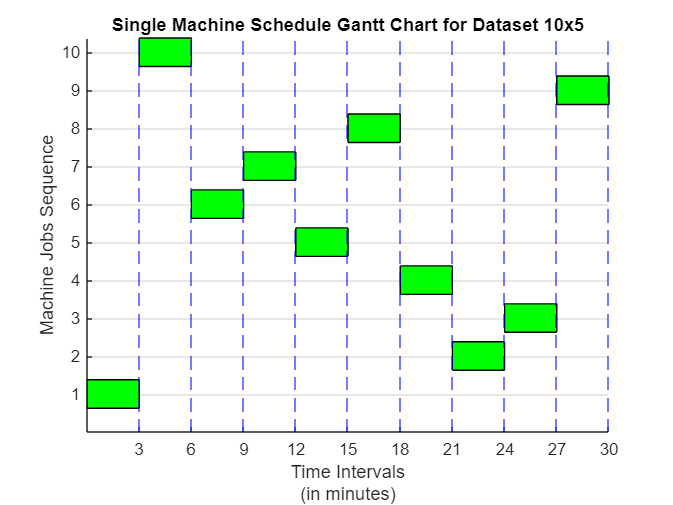

ylim([0 ppp(1,2)])

xline(release_column(:,3),'b--') %'-.b'

%abcd = release_column(6,[2,3,3,2])
%xlim([0 abcd(1,2)+width/2]) % width/2, 1

ylabel({'Machine Jobs Sequence'})
xlabel({'Time Intervals','(in minutes)'})
title('Single Machine Schedule Gantt Chart for Dataset 10x5')

% Add a red frame to the figure.

% f.Units = 'normalized';
% lineWidth = 1; % Whatever you want.
% annotation('line', [0, 0], [0, 1], 'LineWidth', lineWidth, 'Color', 'black');
% annotation('line', [1, 1], [0, 1], 'LineWidth', lineWidth, 'Color', 'black');
% annotation('line', [0, 1], [0, 0], 'LineWidth', lineWidth, 'Color', 'black');
% annotation('line', [1, 0], [1, 1], 'LineWidth', lineWidth, 'Color', 'black');

% https://www.mathworks.com/help/matlab/ref/barh.html ==> keterangan horizontal bar 